# derive_equations_JR.m

Description: Symbolically derive equations related to the jumping robot, including the full nonlinear state-space dynamics.

Inputs: none

Outputs: none

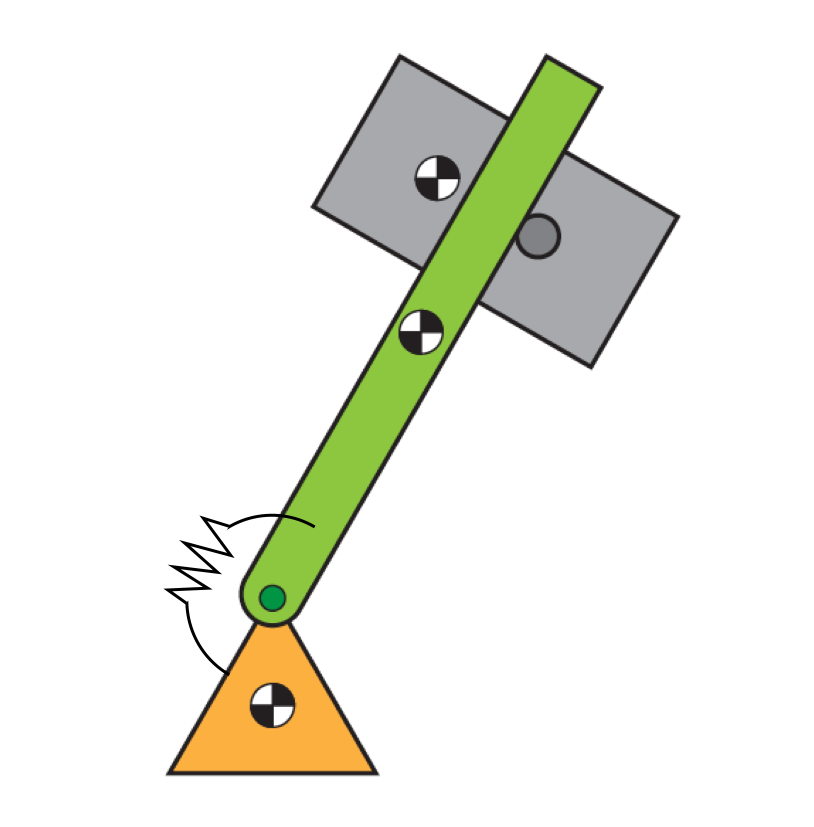

% Script Version:  derive_equations_JR_script.mxl
clear;
close all;
clc;

fprintf('Deriving jumping robot equations...\n');

Deriving jumping robot equations...


## Variable definition

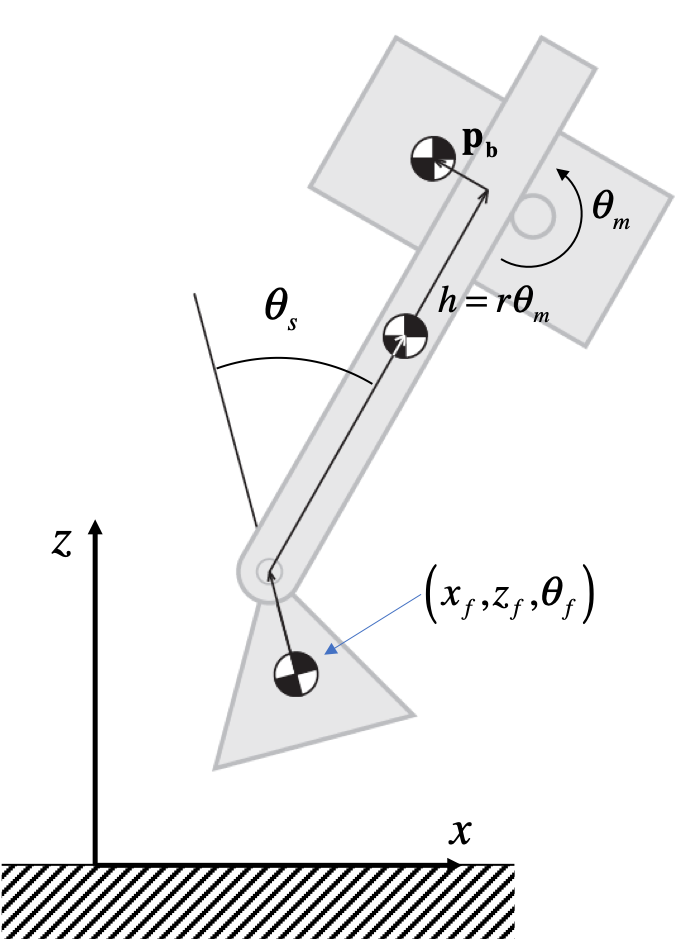 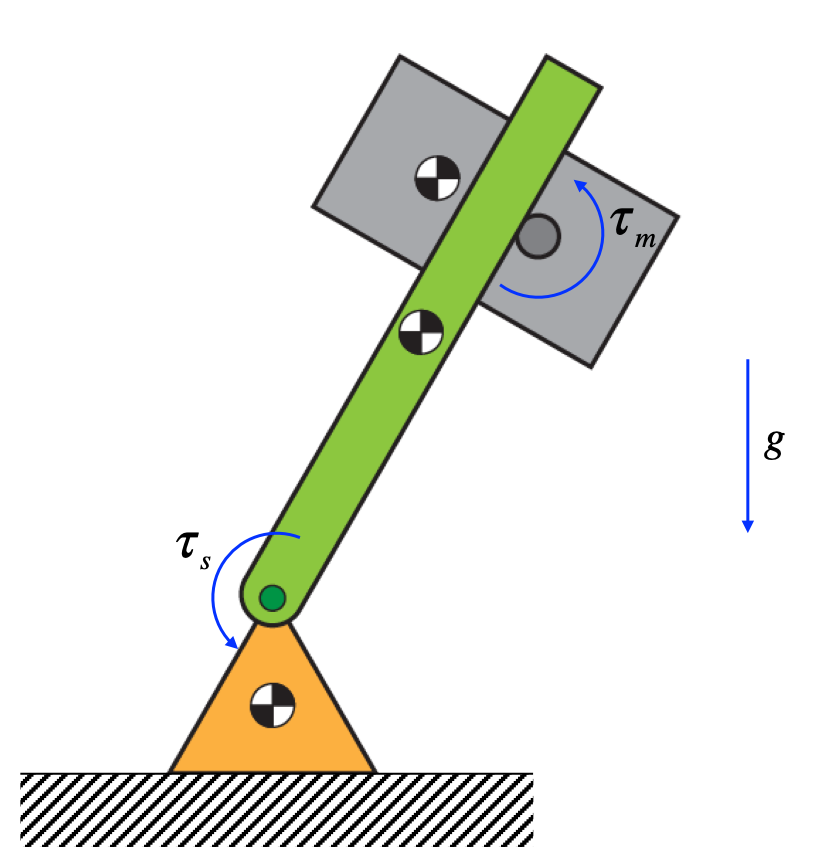

fprintf('\tInitializing generalized coordinates, velocities, accelerations, and forces...\n');

	Initializing generalized coordinates, velocities, accelerations, and forces...



% Generalized coordinates:
% x_f:  horizontal displacement of foot CoM
% z_f:  vertical displacement of foot CoM
% theta_f: angle of the foot relative to ground; positive cw
% theta_s: angle of the spine relative to foot; positive cw
% theta_m: angle of the motor; positive ccw
syms x_f z_f theta_f theta_s theta_m real
q = [x_f; z_f; theta_f; theta_s; theta_m];

% Generalized velocities:
syms x_dot_f z_dot_f theta_dot_f theta_dot_s theta_dot_m real
q_dot = [x_dot_f; z_dot_f; theta_dot_f; theta_dot_s; theta_dot_m]

$$q\_dot = \left(\begin{array}{c} {\dot{x}}_{f}\\ {\dot{z}}_{f}\\ {\dot{\theta }}_{f}\\ {\dot{\theta }}_{s}\\ {\dot{\theta }}_{m} \end{array}\right)$$


% Generalized accelerations:
syms x_ddot_f z_ddot_f theta_ddot_f theta_ddot_s theta_ddot_m real
q_ddot = [x_ddot_f; z_ddot_f; theta_ddot_f; theta_ddot_s; theta_ddot_m]

$$q\_ddot = \left(\begin{array}{c} {\ddot{x}}_{f}\\ {\ddot{z}}_{f}\\ {\ddot{\theta }}_{f}\\ {\ddot{\theta }}_{s}\\ {\ddot{\theta }}_{m} \end{array}\right)$$


% Generalized forces:
% tau_s: torque at base of spine; positive cw
% tau_m: motor torque on body motor; positive ccw
syms tau_s tau_m real 
Q = [0; 0; 0; tau_s; tau_m];

fprintf('\t...done.\n');

	...done.


## Inertial (and other) parameters

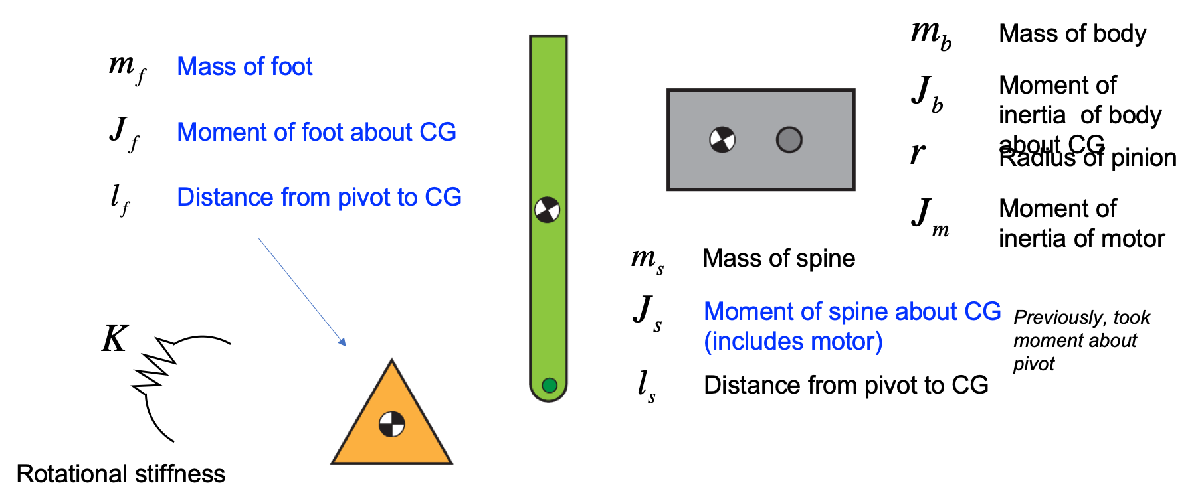

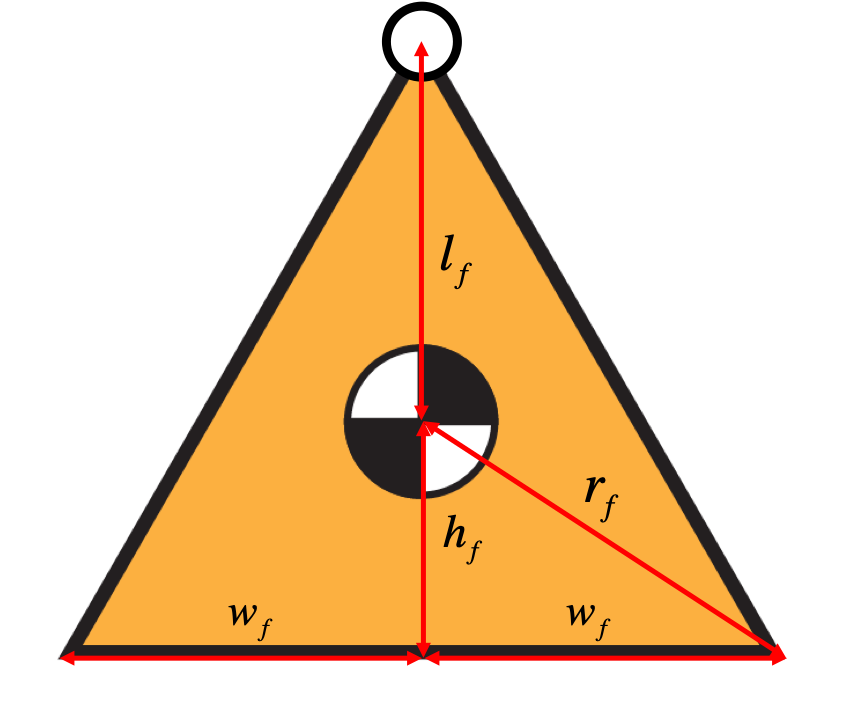

A couple of other parameters include h_b, the height of the body, and l_spine, the length of the spine.

fprintf('\tInitializing inertial (and other) parameters...\n');

	Initializing inertial (and other) parameters...



% Mass of each body:
syms m_f m_s m_b real

% Rotational inertia of each component:
syms J_f J_s J_b J_m real

% Stiffness between sping and foot:
syms K real

% Geometry:
syms l_s p_b h_b r h_f w_f l_f l_spine real

% Other variables
g = sym('g','real'); % gravity
% t = sym('t','real'); % time

fprintf('\t...done.\n');

	...done.


## CoM Forward Kinematics

Here the goal is to find the CoM motion of the spine and body in terms of the generalized coordinates (the foot is trivial)

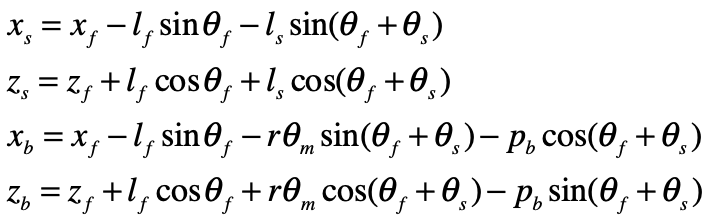

fprintf('\tInitializing kinematics variables...\n');

	Initializing kinematics variables...



% x and z coordinates of the spine and body CoM:
syms x_s z_s x_b z_b real

x_s = x_f - l_f*sin(theta_f) - l_s*sin(theta_f + theta_s);
z_s = z_f + l_f*cos(theta_f) + l_s*cos(theta_f + theta_s);
x_b = x_f - l_f*sin(theta_f) - r*theta_m*sin(theta_f + theta_s) - p_b*cos(theta_f + theta_s);
z_b = z_f + l_f*cos(theta_f) + r*theta_m*cos(theta_f + theta_s) - p_b*sin(theta_f + theta_s);

% create 2x1 arrays to hold the CoM forward kinematics (FK) outputs:
FK_com_s = [x_s; z_s];
FK_com_b = [x_b; z_b];

% coordinates of the pivot and the spine tip to help animate
syms x_pivot z_pivot x_tip z_tip real

x_pivot = x_f - l_f*sin(theta_f);
z_pivot = z_f + l_f*cos(theta_f);
x_tip = x_f - l_f*sin(theta_f) - l_spine*sin(theta_f + theta_s);
z_tip = z_f + l_f*cos(theta_f) + l_spine*cos(theta_f + theta_s);

% create 2x1 arrays to hold the Visualization forward kinematics (FK) outputs:
FK_pivot = [x_pivot; z_pivot];
FK_tip = [x_tip; z_tip];

fprintf('\t...done.\n');

	...done.


fprintf('\tGenerating forward kinematics equations...\n');

	Generating forward kinematics equations...



% generate MATLAB functions to compute all the FK outputs:
matlabFunction(FK_com_s,FK_com_b,'File','autogen_fk_com');
matlabFunction(FK_pivot,FK_tip,'File','autogen_fk_viz');
% Note: these autogenerated functions will make plotting/animation easier
% later. Could also help with some control tasks.
fprintf('\t...done.\n');

	...done.


## Constraint Equations

Here we write out the two constraint equations that are in play when the foot is on the ground, and the two constraint equations that keep the body on the spine.  The foot constraints come from each bottom corner not penetrating the floor, which may be curved.  Note that I am now assuming the foot is frictionless, just to make things a bit simpler.

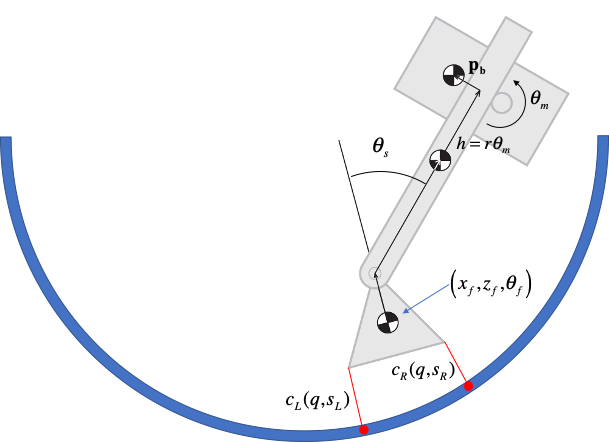

The two constraint equations are $c_L \left(q,s_L \right)\le 0$ and $c_R \left(q,s_R \right)\le 0$.  Here we have two new variables, $s_L$ and $s_R$, which are pathlength variables that describe positions of the red dots:  the points closest to the two feet.  We will need to write additional state equations that help us update those two variables, but we will do that in other functions.  For now, we need only assume that we have a function available which, given a pathlength, returns the x and z coordinates of the corresponding point, as well as the unit tangent and unit normal vectors at that point.  

If we define $r_L \left(q\right)$ as a vector from the global origin to the left foot and $p_L \left(s_L \right)$as a vector from the global origin to the associated red dot, and if $n_L$ is a unit normal pointing into the floor, then we can write:


$$c_L \left(q,s_L \right)={\left(r_L \left(q\right)-p_L \left(s_L \right)\right)}^T n_L$$


This is really just the dot product of the vector from the red dot to the foot with the unit normal, giving the distance of the left foot off the ground in the direction of the normal (actually, the negative distance).  If the red dot has been properly placed, that vector is along the direction of the normal, so it is just the negative length of the vector.

fprintf('\tInitializing constraint variables...\n');

	Initializing constraint variables...



% foot coordinates
syms r_lx r_lz r_rx r_rz real

r_lx = x_f + h_f*sin(theta_f) - w_f*cos(theta_f);
r_rx = x_f + h_f*sin(theta_f) + w_f*cos(theta_f);
r_lz = z_f - h_f*cos(theta_f) - w_f*sin(theta_f);
r_rz = z_f - h_f*cos(theta_f) + w_f*sin(theta_f);

FK_r_l = [r_lx;r_lz];
FK_r_r = [r_rx;r_rz];

% constraint surface variables
syms p_lx p_lz p_rx p_rz n_lx n_lz n_rx n_rz real

% four constraint variables:
syms c_l c_r c_top c_bot real

% unilateral foot
c_l = (r_lx - p_lx)*n_lx + (r_lz - p_lz)*n_lz;
c_r = (r_rx - p_rx)*n_rx + (r_rz - p_rz)*n_rz;

% unilateral body/spine
c_top = r*theta_m - l_spine + 0.5*h_b;
c_bot = 0.5*h_b - r*theta_m;

% create an array to hold constraints:
C_unilateral = [c_l; c_r; c_top; c_bot];

fprintf('\t...done.\n');

	...done.


fprintf('\tGenerating constraint equations...\n');

	Generating constraint equations...



% generate MATLAB functions to compute all the constraints:
matlabFunction(FK_r_l,FK_r_r,'File','autogen_fk_feet');
matlabFunction(C_unilateral,'File','autogen_constraints');
fprintf('\t...done.\n');

	...done.


## Derivatives

Here we take derivatives of both the forward kinematics and the constraint equations

fprintf('\tGenerating time derivatives of the kinematics equations...\n');

	Generating time derivatives of the kinematics equations...



syms dFK_com_s dFK_com_b A_all H_clx H_clz H_crx H_crz real

% Body CoM velocities:
dFK_com_s = jacobian(FK_com_s,q)*q_dot

$$dFK\_com\_s = \left(\begin{array}{c} {\dot{x}}_{f}-{\dot{\theta }}_{f}\,\left(l_{s}\,\cos\left(\theta_{f}+\theta_{s}\right)+l_{f}\,\cos\left(\theta_{f}\right)\right)-l_{s}\,{\dot{\theta }}_{s}\,\cos\left(\theta_{f}+\theta_{s}\right)\\ {\dot{z}}_{f}-{\dot{\theta }}_{f}\,\left(l_{s}\,\sin\left(\theta_{f}+\theta_{s}\right)+l_{f}\,\sin\left(\theta_{f}\right)\right)-l_{s}\,{\dot{\theta }}_{s}\,\sin\left(\theta_{f}+\theta_{s}\right) \end{array}\right)$$

dFK_com_b = jacobian(FK_com_b,q)*q_dot

$$dFK\_com\_b = \begin{array}{l} \left(\begin{array}{c} {\dot{x}}_{f}-{\dot{\theta }}_{f}\,\left(l_{f}\,\cos\left(\theta_{f}\right)-\sigma_{3}+\sigma_{2}\right)+{\dot{\theta }}_{s}\,\left(\sigma_{3}-\sigma_{2}\right)-r\,{\dot{\theta }}_{m}\,\sin\left(\theta_{f}+\theta_{s}\right)\\ {\dot{z}}_{f}-{\dot{\theta }}_{f}\,\left(\sigma_{4}+l_{f}\,\sin\left(\theta_{f}\right)+\sigma_{1}\right)-{\dot{\theta }}_{s}\,\left(\sigma_{4}+\sigma_{1}\right)+r\,{\dot{\theta }}_{m}\,\cos\left(\theta_{f}+\theta_{s}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r\,\theta_{m}\,\sin\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{2}=r\,\theta_{m}\,\cos\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{3}=p_{b}\,\sin\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{4}=p_{b}\,\cos\left(\theta_{f}+\theta_{s}\right) \end{array}$$

dFK_leftfoot = jacobian(FK_r_l,q)*q_dot

$$dFK\_leftfoot = \left(\begin{array}{c} {\dot{x}}_{f}+{\dot{\theta }}_{f}\,\left(h_{f}\,\cos\left(\theta_{f}\right)+w_{f}\,\sin\left(\theta_{f}\right)\right)\\ {\dot{z}}_{f}-{\dot{\theta }}_{f}\,\left(w_{f}\,\cos\left(\theta_{f}\right)-h_{f}\,\sin\left(\theta_{f}\right)\right) \end{array}\right)$$

dFK_rightfoot = jacobian(FK_r_r,q)*q_dot

$$dFK\_rightfoot = \left(\begin{array}{c} {\dot{x}}_{f}+{\dot{\theta }}_{f}\,\left(h_{f}\,\cos\left(\theta_{f}\right)-w_{f}\,\sin\left(\theta_{f}\right)\right)\\ {\dot{z}}_{f}+{\dot{\theta }}_{f}\,\left(w_{f}\,\cos\left(\theta_{f}\right)+h_{f}\,\sin\left(\theta_{f}\right)\right) \end{array}\right)$$


% Constraint equations first and second derivatives
A_unilateral = jacobian(C_unilateral,q)

$$A\_unilateral = \left(\begin{array}{ccccc} n_{\mathrm{lx}} & n_{\mathrm{lz}} & n_{\mathrm{lx}}\,\left(h_{f}\,\cos\left(\theta_{f}\right)+w_{f}\,\sin\left(\theta_{f}\right)\right)-n_{\mathrm{lz}}\,\left(w_{f}\,\cos\left(\theta_{f}\right)-h_{f}\,\sin\left(\theta_{f}\right)\right) & 0 & 0\\ n_{\mathrm{rx}} & n_{\mathrm{rz}} & n_{\mathrm{rx}}\,\left(h_{f}\,\cos\left(\theta_{f}\right)-w_{f}\,\sin\left(\theta_{f}\right)\right)+n_{\mathrm{rz}}\,\left(w_{f}\,\cos\left(\theta_{f}\right)+h_{f}\,\sin\left(\theta_{f}\right)\right) & 0 & 0\\ 0 & 0 & 0 & 0 & r\\ 0 & 0 & 0 & 0 & -r \end{array}\right)$$

H_cl = hessian(c_l,q)

$$H\_cl = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & n_{\mathrm{lx}}\,\left(w_{f}\,\cos\left(\theta_{f}\right)-h_{f}\,\sin\left(\theta_{f}\right)\right)+n_{\mathrm{lz}}\,\left(h_{f}\,\cos\left(\theta_{f}\right)+w_{f}\,\sin\left(\theta_{f}\right)\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

H_cr = hessian(c_r,q)

$$H\_cr = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & n_{\mathrm{rz}}\,\left(h_{f}\,\cos\left(\theta_{f}\right)-w_{f}\,\sin\left(\theta_{f}\right)\right)-n_{\mathrm{rx}}\,\left(w_{f}\,\cos\left(\theta_{f}\right)+h_{f}\,\sin\left(\theta_{f}\right)\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

H_ctop = hessian(c_top,q)

$$H\_ctop = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

H_cbot = hessian(c_bot,q)

$$H\_cbot = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


% generate MATLAB functions for the Jacobians and Hessians:
matlabFunction(dFK_leftfoot,dFK_rightfoot,'File','autogen_foot_velocities');
matlabFunction(dFK_com_s,dFK_com_b,'File','autogen_jacobians');
matlabFunction(A_unilateral,H_cl,H_cr,H_ctop,H_cbot,'File','autogen_constraint_derivatives');

fprintf('\t...done.\n');

	...done.


## Kinetic energy

Sum up:

- Foot translational

- Foot rotational

- Spine translational

- Spine rotational

- Body translational

- Body rotational

- Motor rotational

% fprintf('\tGenerating kinetic energy equation...\n');
% 
% syms ke_f ke_s ke_b KE real
% 
% % kinetic energy of each body:
% ke_f = 0.5*J_f*theta_dot_f^2 + 0.5*m_f*(x_dot_f^2 + z_dot_f^2);
% ke_s = 0.5*J_s*(theta_dot_f + theta_dot_s)^2 + 0.5*m_s*(dFK_com_s'*dFK_com_s);
% ke_b = 0.5*J_b*(theta_dot_f + theta_dot_s)^2 + 0.5*m_b*(dFK_com_b'*dFK_com_b) + 0.5*J_m*(theta_dot_m + theta_dot_f + theta_dot_s)^2;
% 
% % total kinetic energy:
% KE = ke_f + ke_s + ke_b
% 
% fprintf('\t...done.\n');

## Potential energy

Sum up:

- Gravitational potential of foot

- Gravitational potential of spine

- Gravitational potential of body

- Spring

Note:  does not include virtual work done by constraints

% fprintf('\tGenerating potential energy equation...\n');
% 
% syms pe_f pe_s pe_b pe_spring real
% 
% % potential energy of each body:
% pe_f = m_f*g*(z_f - h_f);
% pe_s = m_s*g*(z_s - l_s - l_f - h_f);
% pe_b = m_b*g*(z_b - l_f - h_f);
% pe_spring = 0.5*K*theta_s^2;
% 
% % total potential energy:
% PE = pe_f + pe_s + pe_b + pe_spring
% 
% fprintf('\t...done.\n');

## Euler-Lagrange equations

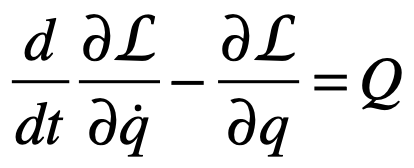

% fprintf('\tGenerating Euler-Lagrange equations of motion...\n')
% 
% % Variable initializations:
% del_L_del_qdot = sym('del_L_del_qdot',[numel(q),1],'real'); % del L/del q_dot
% ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d(del L/del dq)/dt
% ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del q
% 
% del_L_del_qdot = jacobian(KE,q_dot)';
% ELeq_term1 = simplify(jacobian(del_L_del_qdot,[q;q_dot])*[q_dot;q_ddot])
% ELeq_term2 = simplify(jacobian((KE-PE),q))'
% % Note: no constraint forces yet
% 
% fprintf('\t...done.\n')

## Finding the mass matrix and H(q,q_dot)

Note: the highest order derivative that shows up in the Euler-Lagrange Equations is second:  q_ddot  (accelerations).  Our goal is to obtain equations for q_ddot in terms of the state q, state derivatives q_dot, and generalized forces (i.e., the motor torques) Q.  These equations can then be integrated forward in time.  Fortunately, the accelerations always show up linearly and the matrix that multiplies them, the "mass matrix" is guaranteed to be invertible:

      M(q)*q_ddot + H(q,q_dot) = Q

Note that this equation is a generalization of F=ma. It represents the *inverse* dynamics, mapping positions, velocities, and accelerations of the joints to forces or torques (depending on the nature of each joint).

Important note:  there is additional structure in H that is often important to know about.  We won't go into that here.

% fprintf('\tSolving for the mass matrix...\n');
% 
% M = sym('M',[numel(q),numel(q)],'real');
% H = sym('H',[numel(q),1],'real');
% 
% M = simplify(jacobian(del_L_del_qdot,q_dot))
% H = simplify(jacobian(del_L_del_qdot,q)*q_dot - ELeq_term2)
% 
% fprintf('\t\t...done building M and H.\n');


## Finding the inverse mass matrix

Note: we need inv(M) to compute the fwd. dynamics and therefore the state-space dynamics (see below), so to ease computation cost we derive inv(M) symbolically here and autogenerate a dedicated MATLAB function for evaluating it.


% compute and store inv(M):
% fprintf('\t\tComputing inv(M)...\n')
% Minv = sym('Minv',[numel(q),numel(q)],'real');
% Minv = simplify(inv(M))
% fprintf('\t\t...done.\n')
% 
% fprintf('\t\tGenerating MATLAB functions...\n');
% matlabFunction(M,'File','autogen_mass_matrix');
% matlabFunction(Minv,'File','autogen_inverse_mass_matrix');
% matlabFunction(H,'File','autogen_H_eom');
% fprintf('\t\t...done.\n');

## Done!

fprintf('...done deriving cart-pendulum equations.\n');

...done deriving cart-pendulum equations.
